%% Load In all the DataFrom Steven
load("/home/doshna/Downloads/MassVarFLORA.mat")

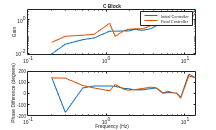

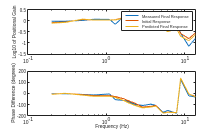

%% Lets get the Ci and Cf for all the data 
[Ci1, Cf1, Hhatf1]=PntMcBlockSolver(data091815_run1(1).peak_RIX, data091815_run1(5).peak_RIX, 1.443*10^(-3), 1.855*10^(-3));

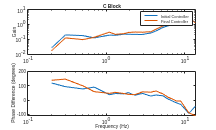

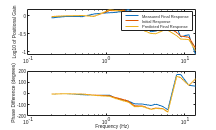



[Ci2, Cf2, Hhatf2]=PntMcBlockSolver(data100515_run2(1).peak_RIX, data100515_run2(5).peak_RIX, 1.651*10^(-3), 1.933*10^(-3));

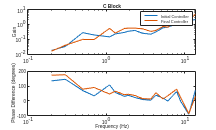

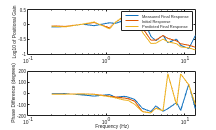



[Ci3, Cf3, Hhatf3]=PntMcBlockSolver(data102015_run1(1).peak_RIX, data102015_run1(5).peak_RIX, 1.765*10^(-3), 2.175*10^(-3));

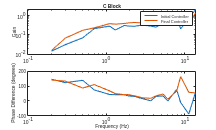

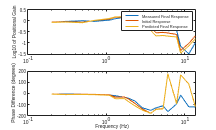



[Ci4, Cf4, Hhatf4]=PntMcBlockSolver(data102815_run3(1).peak_RIX, data102815_run3(5).peak_RIX, 1.546*10^(-3), 2.019*10^(-3));

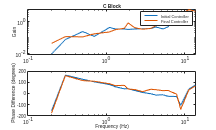

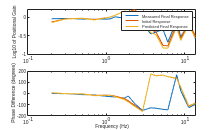



[Ci5, Cf5, Hhatf5]=PntMcBlockSolver(data021116_run3(1).peak_RIX, data021116_run3(5).peak_RIX, 2.207*10^(-3), 2.523*10^(-3));

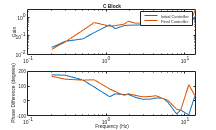

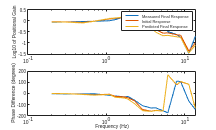



[Ci6, Cf6, Hhatf6]=PntMcBlockSolver(data080416_run2(1).peak_RIX, data080416_run2(5).peak_RIX, 1.642*10^(-3), 2.036*10^(-3));

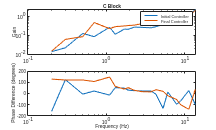

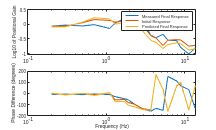



[Ci7, Cf7, Hhatf7]=PntMcBlockSolver(data080916_run2(1).peak_RIX, data080916_run2(5).peak_RIX, 1.52*10^(-3), 2.006*10^(-3));

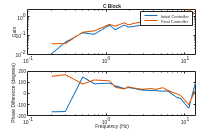

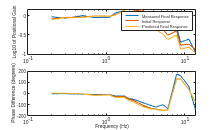



[Ci8, Cf8, Hhatf8]=PntMcBlockSolver(data080916_run5(1).peak_RIX, data080916_run5(5).peak_RIX, 1.457*10^(-3), 1.799*10^(-3));

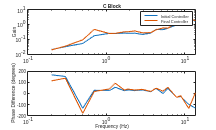

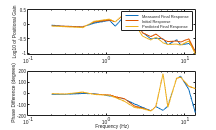



[Ci9, Cf9, Hhatf9]=PntMcBlockSolver(data092116_run2(1).peak_RIX, data092116_run2(5).peak_RIX, 1.744*10^(-3), 2.141*10^(-3));

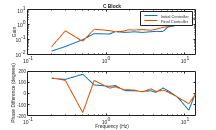

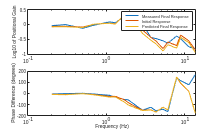



[Ci10, Cf10, Hhatf10]=PntMcBlockSolver(data111816_run1(1).peak_RIX, data111816_run1(5).peak_RIX, 2.146*10^(-3), 2.557*10^(-3));





Ci = horzcat(Ci1,Ci2,Ci3,Ci4,Ci5,Ci6,Ci7,Ci8,Ci9,Ci10);
Cf = horzcat(Cf1,Cf2,Cf3,Cf4,Cf5,Cf6,Cf7,Cf8,Cf9,Cf10);


## Moth Names   

moth_names = ["091815_run1","100515_run2","102015_run1","102815_run3","021116_run3","080416_run2","080916_run2","080916_run5","092116_run2","111816_run1"]

moth_names = 1×10 string array
    "091815_run1"    "100515_run2"    "102015_run1"    "102815_run3"    "021116_run3"    "080416_run2"    "080916_run2"    "080916_run5"    "092116_run2"    "111816_run1"


## Get the Tracking Responses

hi = zeros(18,10);
hf = zeros(18,10);
for i = 1:10 
   val = evalin('base',"data"+moth_names(i));
   hi(:,i) = val(1).peak_RIX;
   hf(:,i) = val(5).peak_RIX; 
end

## Save Away

save("seteven_data_pnt.mat","moth_names","hi","hf","Ci","Cf")
  